# Plot turning frequency vs. [IPTG]

by Ercag, October 2021

clearvars;
clc;
close all; 

## Define Export Path for figures

ExpPath = 'C:\Users\ercagp\Box\Research\VibrioFischeri_Project\Data\RunReverseAnalysis\EventRates';

## Call the run reserve analysis files

MainPath = 'C:\Users\ercagp\Documents\Rowland_Data\RunReverseAnalysis\RunReverse_Data';
StrainLabels = {'KMT47'};

## Input parameters

%Acquisition and ADMM parameter
fps = 30; %Hz
Lambda = 0.5; 

%Time stamp for the PNG/PDF files
Stamp =  ['[' char(datetime('now','Format','yyyyMMdd')) ']'];

%RegExp Keys
RegKeyROI = 'ROI[_]\d';
RegKeyVD = ['(?<=RunReverse_Data' filesep filesep ')\d*'];


%Plot parameters 
PP.Lab.XAx = '[IPTG] (\muM)'; 
PP.Lab.YAx = 'Turn Frequency (sec^{-1})';
PP.Lim.X  = [-5 105]; 
PP.Lim.Y  = [0 1.5]; 
ColorMap = linspecer(3,'qualitative');

if length(StrainLabels) == 1 
    i = 1; 
    if strcmp(StrainLabels{i}, 'KMT43')
       ColorPlot = ColorMap(1,:);
    elseif strcmp(StrainLabels{i},'KMT47')
       ColorPlot = ColorMap(2,:);
    else
       ColorPlot = ColorMap(3,:);
    end
end


## Calculate Turn Frequency for each [IPTG] and take the average

for j = 1:length(StrainLabels)
    Files = callResultsv2(MainPath, StrainLabels{j},Lambda);    

 **Find ROIs and Video dates**

    VideoDates = regexp(Files,RegKeyVD,'match','once');
    ROI = regexp(Files,RegKeyROI,'match','once');  

 **Preallocate**

    IPTG = zeros(length(Files),1);
    TurnSum = cell(length(Files),2);
    TrajDur = cell(length(Files),2);
    TurnFreq = cell(length(Files),2);

  **Call each file **               

    for i = 1:length(Files) 
        load(Files{i})
        fprintf(['minimum T =' num2str(Results.minT) 'sec \n'])
        fprintf(['minimum V =' num2str(Results.minV) 'um/sec \n \n'])
        fprintf(['[IPTG] = ' num2str(RunReverse.Info.IPTG) 'uM \n \n'])

  **IPTG values **      

        IPTG(i) = RunReverse.Info.IPTG; 
        if IPTG(i) == 1
           IPTG(i) = IPTG(i)*1000; %1000uM
        end
        
        %IPTG vector for the plot 
        if strcmp(StrainLabels{j},'KMT53')
            IPTG_X = [0, 25, 50, 60, 75, 100, 1000]; 
        else
            IPTG_X = [0, 25, 35, 50, 60, 75, 100, 1000]; 
        end            

**Total number of turns         **

        TurnSum{i,1} = IPTG(i); 
        TurnSum{i,2} = RunReverse.TotalTurns;

**Filter the slower bugs out**

        FltMask =  filterout(Speeds,Results.minT,Results.minV,fps);
        SpeedSubset = Speeds(FltMask); 

**Total trajectory durations per bug**

        TrajDur{i,1} = IPTG(i); 
        TrajDur{i,2} = sum(cellfun(@(x) size(x(:,1),1)./fps,SpeedSubset));                                              

**Turn frequency per [IPTG] (i.e., acquisition) **

        TurnFreq{i,1} = IPTG(i);
        TurnFreq{i,2} = TurnSum{i,2}/TrajDur{i,2};
    end

**Plot the turn frequencies as a function of [IPTG]**        

minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 35uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 0uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 100uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 75uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 25uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 60uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 1uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


minimum T =0sec 


minimum V =20um/sec 
 


[IPTG] = 50uM 
 


IP = struct with fields:
              x: {[0 0 0 25 25 25 35 35 35 100 100 100 50 50 50 75 75 75 35 35 35 0 0 0 25 25 25 35 35 35 50 50 50 0 0 100 100 100 75 75 75 25 25 25 60 60 60 60 60 60 60 60 1000 1000 1000 1000 1000 60 60 60 1000 1000 50 50 50 50 50 50]}
              y: {[1×68 double]}
    MarkerStyle: {'o'}


ax1 =   Axes with properties:

             XLim: [0 100]
             YLim: [-2.4137 5.0268]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0700 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


ax2 =   Axes with properties:

             XLim: [100 10000]
             YLim: [-2.4137 5.0268]
           XScale: 'log'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.8850 0.1100 0.1000 0.8150]
            Units: 'normalized'

  Show all properties


ax2 =   Axes with properties:

             XLim: [100 10000]
             YLim: [-2.4137 5.0268]
           XScale: 'log'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.8850 0.1100 0.1000 0.8150]
            Units: 'normalized'

  Show all properties


ax2 =   Axes with properties:

             XLim: [100 10000]
             YLim: [-2.4137 5.0268]
           XScale: 'log'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.8850 0.1100 0.1000 0.8150]
            Units: 'normalized'

  Show all properties


ax1 =   Axes (KMT47) with properties:

             XLim: [-5 105]
             YLim: [0 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0700 0.1100 0.8000 0.8150]
            Units: 'normalized'

  Show all properties


ax2 =   Axes with properties:

             XLim: [100 10000]
             YLim: [0 3]
           XScale: 'log'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.8850 0.1100 0.1000 0.8150]
            Units: 'normalized'

  Show all properties


mean_TurnFreq =          0    0.1109


mean_TurnFreq =          0    0.1109    0.0469
   25.0000    0.1314         0


mean_TurnFreq =          0    0.1109    0.0469
   25.0000    0.1314    0.0402
   35.0000    0.1327         0


mean_TurnFreq =          0    0.1109    0.0469
   25.0000    0.1314    0.0402
   35.0000    0.1327    0.0453
   50.0000    0.2062         0


mean_TurnFreq =          0    0.1109    0.0469
   25.0000    0.1314    0.0402
   35.0000    0.1327    0.0453
   50.0000    0.2062    0.0640
   60.0000    1.4257         0


mean_TurnFreq =          0    0.1109    0.0469
   25.0000    0.1314    0.0402
   35.0000    0.1327    0.0453
   50.0000    0.2062    0.0640
   60.0000    1.4257    0.7139
   75.0000    1.8678         0


mean_TurnFreq =          0    0.1109    0.0469
   25.0000    0.1314    0.0402
   35.0000    0.1327    0.0453
   50.0000    0.2062    0.0640
   60.0000    1.4257    0.7139
   75.0000    1.8678    0.3082
  100.0000    1.9406         0


mean_TurnFreq = 	1.0e+03 *

         0    0.0001    0.0000
    0.0250    0.0001    0.0000
    0.0350    0.0001    0.0000
    0.0500    0.0002    0.0001
    0.0600    0.0014    0.0007
    0.0750    0.0019    0.0003
    0.1000    0.0019    0.0001
    1.0000    0.0018         0


RegKey_SS = '(?<=KMT47\_)\d*'

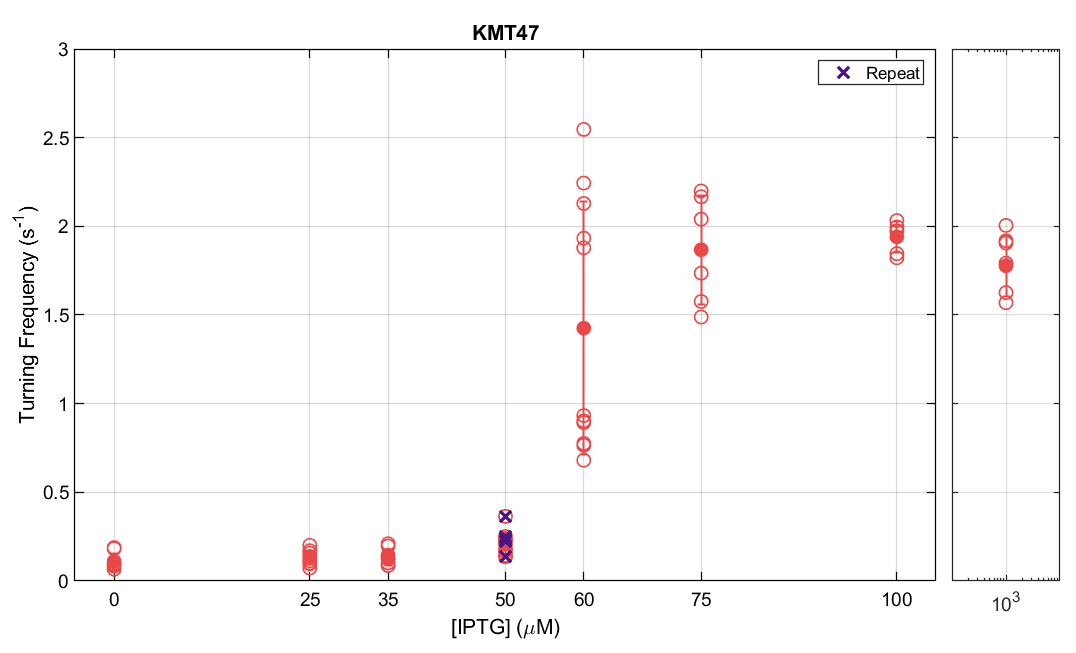

         hFig = figure(j);
                           
         %---Break x-axis---
         IP.x{1} = [TurnFreq{:,1}]; % [IPTG]
         IP.y{1} = [TurnFreq{:,2}];
         
         IP.MarkerStyle{1} = 'o'            
         IP.breakpoint = 150;
         [ax1, ax2, hp1, hp2] = BreakXAxis(IP);
         
         eps = 0.015; 
         ax1.Position(1) = 0.070
         ax1.Position(3) = 0.80;
         ax2.Position(1) = ax1.Position(1) + ax1.Position(3) + eps;
         ax2.Position(3) = 0.100
                
         set([ax1,ax2],'XGrid','on');
         set([ax1,ax2],'YGrid','on');
         ax2.XMinorGrid = 'off'
         ax2.YMinorGrid = 'off'
         ax1.XLim = [-5 105]; 
         ax1.YLim = [0 3];
         ax2.YLim = [0 3];
         
         ax1.XTick = IPTG_X(1:end-1); 
         ax2.XTick = 1000;
         
         ax1.FontSize = 14;
         ax1.FontName = 'Helvetica';
         ax1.Box = 'on'
         ax1.LineWidth = 1;
         
         ax1.XLabel.String = '[IPTG] (\muM)';
         ax1.YLabel.String = 'Turning Frequency (s^{-1})';
         ax1.Title.String = StrainLabels{j};
         
         ax2.FontSize = 14;
         ax2.FontName = 'Helvetica';
         ax2.Box = 'on'
         ax2.LineWidth = 1;
                 
         %Set the color 
         hp1{1}.Color = ColorPlot;
         hp2{1}.Color = ColorPlot;
                         
         
         for k = 1:length(IPTG_X)
             LogMask = [TurnFreq{:,1}] == IPTG_X(k);
             mean_TurnFreq(k,1) = IPTG_X(k);
             mean_TurnFreq(k,2) = mean([TurnFreq{LogMask,2}])
             mean_TurnFreq(k,3) = std([TurnFreq{LogMask,2}],0);                           
         end
         
         hold on 
         axes(ax1)
         err1 = errorbar(mean_TurnFreq(1:end-1,1),mean_TurnFreq(1:end-1,2),mean_TurnFreq(1:end-1,3),'.','MarkerSize',38,...
             'LineWidth',1.5);
         axes(ax2)
         err2 = errorbar(mean_TurnFreq(end,1),mean_TurnFreq(end,2),mean_TurnFreq(end,3),'.','MarkerSize',38,...
             'LineWidth',1.5);
         
         err1.Color = ColorPlot;
         err2.Color = ColorPlot;
                
         
         %----Katja's Concern----
         if strcmp(StrainLabels{j},'KMT53')            
            Mask_Katja = contains(VideoDates,'20210624');
         else 
            %Remove [IPTG] = 1mM cases
            RegKey_SS = ['(?<=' StrainLabels{j} '\_)\d*']                      
            IPTGValues = regexp(Files,RegKey_SS,'match','once');
            Mask_Katja = ( contains(VideoDates,'20210318') | contains(VideoDates,'20210324')...
                        | contains(VideoDates,'20210325') | contains(VideoDates,'20210330') )...
                         & contains(IPTGValues,'50');
         end
         %Switch to ax1 
         axes(ax1);
         Purple = [0.29,0.078,0.52];    
         KTC_p = plot([TurnFreq{Mask_Katja,1}],[TurnFreq{Mask_Katja,2}],'x','MarkerSize',12,'Color',Purple,'LineWidth',2.5);      
         %----Katja's Concern----
         
         legend(KTC_p,'Repeat'); 
         
         set(hFig,'Position', [650 490 1076 653]); 
         %if j == length(StrainLabels)
            %legend([pH{1:end}],StrainLabels,'Location','NorthWest')
            %Export the figure 
            S.ExpPath = ExpPath;
            S.SubDir = 'TurnFrequency_[IPTG]'; 
            S.Stamp = Stamp;
            S.PlotY = [StrainLabels{j} '_TurnFreq_vs_IPTG_KatjasConcern_60uM']; 
            S.ExpType = '';%'Combined'; 
                   
            ExportFig(hFig,S)
         %end
         
end

## Functions 

function [FilterMask] = filterout(S,minT,minV,fps)

         %Filter out trajectories
         TotalTime = cellfun(@(x) length(x(:,1)).*1/fps,S); 
         medV = cellfun(@(x) medianN(x(:,9)), S);
        
         FilterMask = medV > minV & TotalTime > minT;
         %SSubset = S(FilterMask); 
end

function ExportFig(hf,Strings)
                                                        
          
        if strcmp(Strings.ExpType,'PerAcq')
           FinalExpPath = fullfile(Strings.ExpPath,Strings.SubDir,Strings.PlotY,Strings.Strain,[Strings.IPTG 'uM']);
           FullFileName = [Strings.Stamp Strings.Strain '_' Strings.PlotY '_' Strings.VD '_IPTG_' Strings.IPTG 'uM_' Strings.ROI];
        else
           FinalExpPath = fullfile(Strings.ExpPath,Strings.SubDir);
           FullFileName = [Strings.Stamp Strings.PlotY];
        end
        
        if ~exist(FinalExpPath,'dir')
            mkdir(FinalExpPath)
        end   
        printfig(hf,fullfile(FinalExpPath,FullFileName),'-dpng');
        printfig(hf,fullfile(FinalExpPath,FullFileName),'-dpdf');
        savefig(hf,fullfile(FinalExpPath,FullFileName));
end